disp("Opgave 6.1")

Opgave 6.1



clc
clear

syms x
f = @(x) -0.9*x^2 + 1.7*x + 2.5;
df = matlabFunction(diff(f, x));


[root, ea, iter] = newtraph(f, df, 5, 0.001)

root =    2.860104405507428


ea =      9.913886563630006e-06


iter =      5


disp("Opgave 6.2")

Opgave 6.2


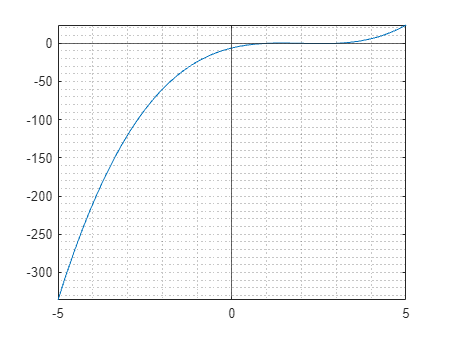


clc
clear

syms x

f = @(x) x.^3 - 6.*x.^2 + 11.*x - 6.1;

df = matlabFunction(diff(f, x));

fplot(f), grid("minor"), xline(0), yline(0)

disp("Svar til 6.2")

Svar til 6.2


[root, ea, iter] = newtraph(f, df, 3.5)

root =    3.046680531805026


ea =      1.821905772468020e-05


iter =      5


disp("Opgave 6.3")

Opgave 6.3


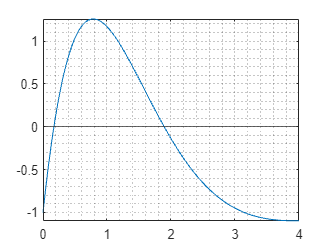


clc
clear
syms x

f = @(x) 7.*exp(-x).*sin(x)-1;

fplot(f, [0, 4]), grid("minor"), xline(0), yline(0)


df = matlabFunction(diff(f, x));

[root, ea, iter] = newtraph(f, df, 0, 0.001, 3)

root = 0.1702

ea = 0.5065

iter = 3


[root, ea, iter] = newtraph(f, df, 2, 0.001, 3)

root = 1.8931

ea = 1.5401e-04

iter = 3

disp("Opgave 6.4")

Opgave 6.4



clc
clear
syms x

f = @(x) -0.9.*x.^2 + 1.7*x + 2.5;

df = matlabFunction(diff(f, x));

[root, ea, iter] = newtraph(f, df, 2, 0.001)

root = 2.8601

ea = 3.2572e-07

iter = 5

disp("Opgave 6.5")

Opgave 6.5



clc
clear
syms x

f = @(x) -2 + 6*x - 4*x.^2 + 0.5*x.^3;
df = matlabFunction(diff(f, x));

x0s = [0.2, 1.8, 5.7, 4.5, 4.43];

for i = 1:length(x0s)
    disp("Resultater for forskellige initial values")
    x0 = x0s(i)
    [root, ea, iter] = newtraph(f, df, x0s(i), 0.001)
end

Resultater for forskellige initial values


x0 = 0.2000

root = 0.4746

ea = 1.2991e-07

iter = 5

Resultater for forskellige initial values


x0 = 1.8000

root = 1.3691

ea = 2.9236e-08

iter = 5

Resultater for forskellige initial values


x0 = 5.7000

root = 6.1563

ea = 1.1506e-04

iter = 4

Resultater for forskellige initial values


x0 = 4.5000

root = 6.1563

ea = 1.0026e-06

iter = 11

Resultater for forskellige initial values


x0 = 4.4300

root = 0.4746

ea = 8.9272e-05

iter = 25

disp("Opgave 6.6")

Opgave 6.6


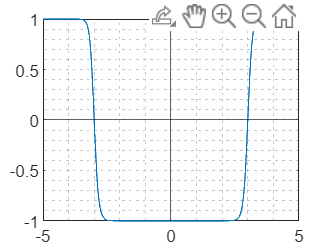


clc
clear
syms x

f = @(x) tanh(x.^2 - 9);
df = matlabFunction(diff(f, x));

fplot(f), grid("minor"), xline(0), yline(0)


[root, ea, iter] = newtraph(f, df, 3.1, 0.001, 3)

xr = 2.9753

xr = 3.0005

xr = 3.0000

root = 3.0000

ea = 0.0154

iter = 3

disp("Opgave 6.7")

Opgave 6.7



clc
clear
syms h r V L

V = (r^2*acos((r-h)/r) - (r-h)*sqrt(2*r*h-h^2))*L

$$V = L\,\left(\left(h-r\right)\,\sqrt{2\,h\,r-h^{2}}+r^{2}\,\left(\pi -\mathrm{acos}\left(\frac{h-r}{r}\right)\right)\right)$$


r = 2; L = 5;  V= 8;

f = @(h) (r^2*acos((r-h)/r) - (r-h)*sqrt(2*r*h-h^2))*L - V;

fzero(f, [0, 2*r])

ans = 0.7400

disp("Opgave 6.8")

Opgave 6.7



clc
clear
syms y y_0 x T_A omega


y = T_A/omega * cosh(omega/T_A * x) + y_0-T_A/omega

$$y = y_{0}-\frac{T_{A}}{\omega }+\frac{T_{A}\,\cosh\left(\frac{\omega \,x}{T_{A}}\right)}{\omega }$$


u = symunit;

omega = 10; y_0 = 5; y = 15; x = 50;

f = @(T_A) T_A/omega * cosh(omega/T_A * x) + y_0-T_A/omega - y;

gs = [100, 500, 1000, 2000];

for i = 1:length(gs)
    [TA,fval] = fzero(f, gs(i))
end

TA = 2.8479e-16

fval = Inf

TA = -3.8959e-16

fval = -Inf

TA = 1.2663e+03

fval = 0

TA = 1.2663e+03

fval = 0

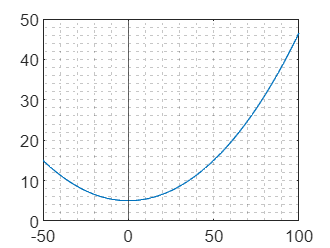



w = 10; y0 = 5; TA = 1266.3;
x = linspace(-50,100);
y = TA/w*cosh(w/TA*x)+y0-TA./w;
plot(x,y), grid("minor"), xline(0), yline(0)

disp("Opgave 6.9")

Opgave 6.9


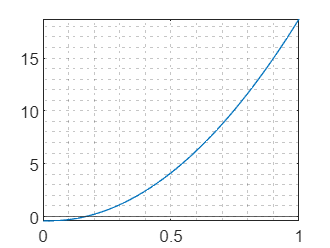


clc
clear
syms d

k1 = 40; k2 = 0.04; m = 0.095; h = 0.43; g = 9.81;

f = @(d) 2*k2*d^(5/2)/5 + k1*d^2/2 - m*g*(h+d);

fplot(f, [0, 1]), grid("minor"), xline(0), yline(0)


[root, funktionsvaerdi] = fzero(f, [0, 0.2])

root = 0.1667

funktionsvaerdi = -1.1102e-16

disp("Opgave 6.10")

Opgave 6.10



clc
clear
syms y g x y_0 nu_0 theta

y = -(g/(2*nu_0^2*cos(theta)^2))*x^2 + tan(theta)*x + y_0

$$y = y_{0}+x\,\tan\left(\theta \right)-\frac{g\,x^{2}}{2\,{\nu_{0}}^{2}\,{\cos\left(\theta \right)}^{2}}$$

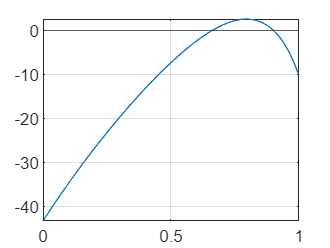


y_0 = 1.8;  nu_0 = 30;  g = 9.81;   y = 1;  x = 90;

f = @(theta) -(g/(2*nu_0^2*cos(theta)^2))*x^2 + tan(theta)*x + y_0 - y;

fplot(f, [0,1]), grid, xline(0), yline(0)


[root1, funcval1] = fzero(f, [0.6, 0.7])

root1 = 0.6625

funcval1 = -1.1324e-14

[root2, funcval2] = fzero(f, [0.8, 0.9])

root2 = 0.8994

funcval2 = -1.1324e-14